# Sistemas 

# Nebulosos - UFMG 2021 

Professor: Walmir Caminhas

Aluno: Luiz Gabriel Aragão 2014806480

# Planta de controle nebuloso direto

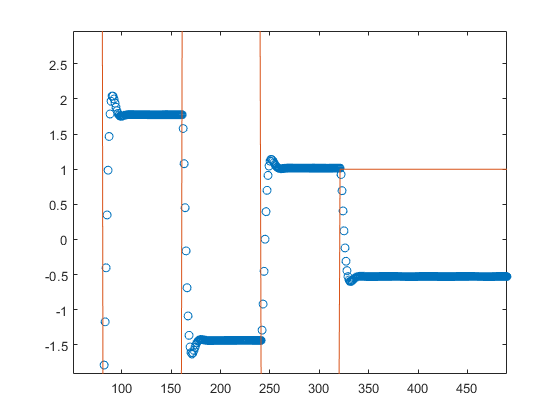

close all;
%clear all;
clc
nPontos=600;
%referenciais
yref(1:80)=5;
yref(81:160)=-4;
yref(161:240)=3;
yref(241:320)=-2;
yref(321:600)=1;

y(1:2)=0;
u(1:2)=0;
ke=0.1;
ks=0.31;


param = readfis('control_fuzzy.fis');
for k=3:nPontos
    y(k)=1.4*y(k-1) -0.6*y(k-2) -3*u(k-1)^3 + 2*u(k-1) -u(k-2)^3 +2*u(k-2);
    erro(k)=yref(k)-y(k);
    u(k) = ks*evalfis(param,ke*erro(k))+ 0.1*u(k-1);
end
%% respota do controlador
plot(y,'-')
hold on 
plot(yref)

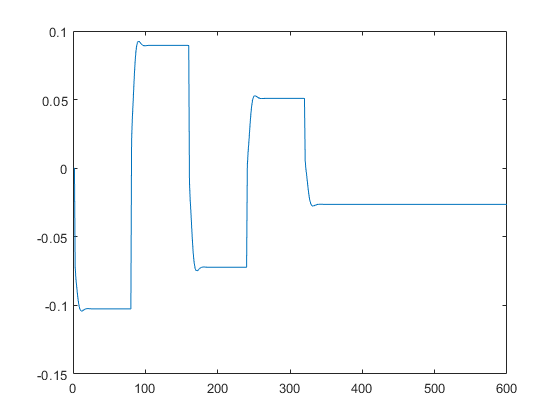

figure
plot(u)